clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.306;6.650;0];
u31=[0.4897;0.8719;0];
r2=[8.454;0;7.345];
u32=[-0.4897;0.8719;0];
r3=[8.454;13.299;7.345];
u33=[-0.4897;0.8719;0];
r4=[9.919;6.650;0];
u34=[-0.4897;-0.8719;0];
r5=[16.531;6.650;0];
u35=[0.4897;0.8719;0];
r6=[0.377;6.650;14.691];
u36=[0.4897;0.8719;0];
r7=[6.990;6.650;14.691];
u37=[-0.4897;-0.8719;0];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
% center and direction of spheroids

hold on
axis([0 10 0 12]);
for R3=1:1:12 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     9.0500    1.0000    1.0019


ans =     8.2700    2.0000    1.0005


ans =     7.4100    3.0000    1.0004


ans =     6.5700    4.0000    1.0003


ans =     5.8800    5.0000    1.0020


ans =     5.3900    6.0000    1.0025


ans =     5.0500    7.0000    1.0008


ans =     4.7900    8.0000    1.0017


ans =     4.5900    9.0000    1.0025


ans =     4.4400   10.0000    1.0009


ans =     4.3100   11.0000    1.0035


ans =     4.2200   12.0000    1.0005



values1 = spcrv([[x1(1) x1 x1(end)];[y1(1) y1 y1(end)]],3);
plot(values1(1,:),values1(2,:),'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[142, 152, 161]/256, ...
    'DisplayName','1-2');


for R1=3.5:0.5:9 %离心率
    R3=8;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3+n;
        R1=R1;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R3=R3-n;
        R1=R1;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     3.5000   15.8100    1.0000


ans =     4.0000    9.9800    1.0002


ans =     4.5000    8.3900    1.0011


ans =     5.0000    7.6300    1.0015


ans =     5.5000    7.1900    1.0007


ans =     6.0000    6.9000    1.0005


ans =     6.5000    6.6900    1.0020


ans =     7.0000    6.5400    1.0023


ans =     7.5000    6.4300    1.0015


ans =     8.0000    6.3400    1.0019


ans =     8.5000    6.2700    1.0018


ans =     9.0000    6.2100    1.0025



values2 = spcrv([[x2(1) x2 x2(end)];[y2(1) y2 y2(end)]],3);
plot(values2(1,:),values2(2,:),'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[238, 148, 138]/256, ...
    'DisplayName','2-3');

for R1=2.9:0.5:10 %离心率
    R3=2;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3+n;
        R1=R1;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R3=R3-n;
        R1=R1;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans =     2.9000   14.9300    1.0000


ans =     3.4000    3.0500    1.0008


ans =     3.9000    2.4000    1.0016


ans =     4.4000    2.1400    1.0018


ans =     4.9000    2.0000    1.0016


ans =     5.4000    1.9100    1.0037


ans =     5.9000    1.8500    1.0049


ans =     6.4000    1.8100    1.0033


ans =     6.9000    1.7800    1.0021


ans =     7.4000    1.7500    1.0080


ans =     7.9000    1.7300    1.0093


ans =     8.4000    1.7200    1.0042


ans =     8.9000    1.7100    1.0017


ans =     9.4000    1.7000    1.0015


ans =     9.9000    1.6900    1.0030



values3 = spcrv([[x3(1) x3 x3(end)];[y3(1) y3 y3(end)]],3);
plot(values3(1,:),values3(2,:),'color',[191, 144, 0]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[223, 199, 127]/256, ...
    'DisplayName','1-4');

for R3=4:0.5:12 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans =     9.8200    4.0000    1.0001


ans =     8.3000    4.5000    1.0003


ans =     7.5600    5.0000    1.0010


ans =     7.1300    5.5000    1.0005


ans =     6.8400    6.0000    1.0017


ans =     6.6400    6.5000    1.0021


ans =     6.5000    7.0000    1.0007


ans =     6.3900    7.5000    1.0005


ans =     6.3000    8.0000    1.0013


ans =     6.2300    8.5000    1.0015


ans =     6.1700    9.0000    1.0026


ans = 1×3
    6.1300    9.5000    1.0008


ans = 1×3
    6.0900   10.0000    1.0011


ans = 1×3
    6.0600   10.5000    1.0002


ans = 1×3
    6.0300   11.0000    1.0008


ans = 1×3
    6.0000   11.5000    1.0026


ans = 1×3
    5.9800   12.0000    1.0023



values4 = spcrv([[x4(1) x4 x4(end)];[y4(1) y4 y4(end)]],3);
plot(values4(1,:),values4(2,:),'color',[56, 87, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-5');

for R1=3.8:0.2:7.8 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    3.8000   15.6900    1.0000


ans = 1×3
    4.0000    9.9000    1.0001


ans = 1×3
    4.2000    7.8700    1.0001


ans = 1×3
    4.4000    6.7400    1.0006


ans = 1×3
    4.6000    6.0000    1.0003


ans = 1×3
    4.8000    5.4500    1.0006


ans = 1×3
    5.0000    5.0200    1.0005


ans = 1×3
    5.2000    4.6600    1.0005


ans = 1×3
    5.4000    4.3500    1.0001


ans = 1×3
    5.6000    4.0600    1.0016


ans = 1×3
    5.8000    3.8000    1.0013


ans = 1×3
    6.0000    3.5500    1.0015


ans = 1×3
    6.2000    3.3100    1.0009


ans = 1×3
    6.4000    3.0700    1.0004


ans = 1×3
    6.6000    2.8200    1.0010


ans = 1×3
    6.8000    2.5600    1.0016


ans = 1×3
    7.0000    2.2900    1.0013


ans = 1×3
    7.2000    2.0000    1.0004


ans = 1×3
    7.4000    1.6700    1.0001


ans = 1×3
    7.6000    1.2700    1.0008


ans = 1×3
    7.8000    0.7400    1.0006



values5 = spcrv([[x5(1) x5 x5(end)];[y5(1) y5 y5(end)]],3);
plot(values5(1,:),values5(2,:),'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[159, 190, 208]/256, ...
    'DisplayName','2-4');

for R3=1:0.2:12 %离心率
    R1=8;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3;
        R1=R1+n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R3=R3;
        R1=R1-n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];  
end

ans = 1×3
   10.7000    1.0000    1.0003


ans = 1×3
    9.3000    1.2000    1.0000


ans = 1×3
    8.6800    1.4000    1.0003


ans = 1×3
    8.3400    1.6000    1.0001


ans = 1×3
    8.1200    1.8000    1.0018


ans = 1×3
    7.9800    2.0000    1.0015


ans = 1×3
    7.8800    2.2000    1.0015


ans = 1×3
    7.8100    2.4000    1.0006


ans = 1×3
    7.7500    2.6000    1.0016


ans = 1×3
    7.7100    2.8000    1.0007


ans = 1×3
    7.6700    3.0000    1.0020


ans = 1×3
    7.6500    3.2000    1.0001


ans = 1×3
    7.6200    3.4000    1.0018


ans = 1×3
    7.6000    3.6000    1.0021


ans = 1×3
    7.5900    3.8000    1.0005


ans = 1×3
    7.5700    4.0000    1.0022


ans = 1×3
    7.5600    4.2000    1.0017


ans = 1×3
    7.5500    4.4000    1.0017


ans = 1×3
    7.5400    4.6000    1.0021


ans = 1×3
    7.5400    4.8000    1.0001


ans = 1×3
    7.5300    5.0000    1.0009


ans = 1×3
    7.5200    5.2000    1.0020


ans = 1×3
    7.5200    5.4000    1.0006


ans = 1×3
    7.5100    5.6000    1.0020


ans = 1×3
    7.5100    5.8000    1.0009


ans = 1×3
    7.5000    6.0000    1.0025


ans = 1×3
    7.5000    6.2000    1.0016


ans = 1×3
    7.5000    6.4000    1.0008


ans = 1×3
    7.5000    6.6000    1.0000


ans = 1×3
    7.4900    6.8000    1.0020


ans = 1×3
    7.4900    7.0000    1.0013


ans = 1×3
    7.4900    7.2000    1.0008


ans = 1×3
    7.4900    7.4000    1.0002


ans = 1×3
    7.4800    7.6000    1.0024


ans = 1×3
    7.4800    7.8000    1.0020


ans = 1×3
    7.4800    8.0000    1.0015


ans = 1×3
    7.4800    8.2000    1.0012


ans = 1×3
    7.4800    8.4000    1.0008


ans = 1×3
    7.4800    8.6000    1.0005


ans = 1×3
    7.4800    8.8000    1.0001


ans = 1×3
    7.4700    9.0000    1.0025


ans = 1×3
    7.4700    9.2000    1.0022


ans = 1×3
    7.4700    9.4000    1.0020


ans = 1×3
    7.4700    9.6000    1.0017


ans = 1×3
    7.4700    9.8000    1.0015


ans = 1×3
    7.4700   10.0000    1.0013


ans = 1×3
    7.4700   10.2000    1.0011


ans = 1×3
    7.4700   10.4000    1.0009


ans = 1×3
    7.4700   10.6000    1.0007


ans = 1×3
    7.4700   10.8000    1.0006


ans = 1×3
    7.4700   11.0000    1.0004


ans = 1×3
    7.4700   11.2000    1.0003


ans = 1×3
    7.4700   11.4000    1.0001


ans = 1×3
    7.4600   11.6000    1.0027


ans = 1×3
    7.4600   11.8000    1.0025


ans = 1×3
    7.4600   12.0000    1.0024



values6 = spcrv([[x6(1) x6 x6(end)];[y6(1) y6 y6(end)]],3);
plot(values6(1,:),values6(2,:),'color',[237, 125, 49]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[237, 125, 49]/256, ...
    'DisplayName','1-6');


for R3=1.3:0.2:12 %离心率
    R1=8;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3;
        R1=R1+n;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R3=R3;
        R1=R1-n;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];  
end

ans = 1×3
   10.4400    1.3000    1.0004


ans = 1×3
    9.4100    1.5000    1.0002


ans = 1×3
    8.8700    1.7000    1.0002


ans = 1×3
    8.5400    1.9000    1.0006


ans = 1×3
    8.3200    2.1000    1.0012


ans = 1×3
    8.1700    2.3000    1.0008


ans = 1×3
    8.0600    2.5000    1.0005


ans = 1×3
    7.9700    2.7000    1.0017


ans = 1×3
    7.9100    2.9000    1.0003


ans = 1×3
    7.8500    3.1000    1.0021


ans = 1×3
    7.8100    3.3000    1.0016


ans = 1×3
    7.7800    3.5000    1.0005


ans = 1×3
    7.7500    3.7000    1.0007


ans = 1×3
    7.7200    3.9000    1.0021


ans = 1×3
    7.7000    4.1000    1.0019


ans = 1×3
    7.6900    4.3000    1.0000


ans = 1×3
    7.6700    4.5000    1.0012


ans = 1×3
    7.6600    4.7000    1.0004


ans = 1×3
    7.6400    4.9000    1.0025


ans = 1×3
    7.6300    5.1000    1.0024


ans = 1×3
    7.6300    5.3000    1.0001


ans = 1×3
    7.6200    5.5000    1.0006


ans = 1×3
    7.6100    5.7000    1.0013


ans = 1×3
    7.6000    5.9000    1.0022


ans = 1×3
    7.6000    6.1000    1.0007


ans = 1×3
    7.5900    6.3000    1.0019


ans = 1×3
    7.5900    6.5000    1.0006


ans = 1×3
    7.5800    6.7000    1.0021


ans = 1×3
    7.5800    6.9000    1.0011


ans = 1×3
    7.5800    7.1000    1.0001


ans = 1×3
    7.5700    7.3000    1.0018


ans = 1×3
    7.5700    7.5000    1.0010


ans = 1×3
    7.5700    7.7000    1.0003


ans = 1×3
    7.5600    7.9000    1.0022


ans = 1×3
    7.5600    8.1000    1.0016


ans = 1×3
    7.5600    8.3000    1.0010


ans = 1×3
    7.5600    8.5000    1.0005


ans = 1×3
    7.5500    8.7000    1.0026


ans = 1×3
    7.5500    8.9000    1.0021


ans = 1×3
    7.5500    9.1000    1.0016


ans = 1×3
    7.5500    9.3000    1.0012


ans = 1×3
    7.5500    9.5000    1.0008


ans = 1×3
    7.5500    9.7000    1.0005


ans = 1×3
    7.5500    9.9000    1.0001


ans = 1×3
    7.5400   10.1000    1.0024


ans = 1×3
    7.5400   10.3000    1.0021


ans = 1×3
    7.5400   10.5000    1.0018


ans = 1×3
    7.5400   10.7000    1.0015


ans = 1×3
    7.5400   10.9000    1.0013


ans = 1×3
    7.5400   11.1000    1.0010


ans = 1×3
    7.5400   11.3000    1.0008


ans = 1×3
    7.5400   11.5000    1.0006


ans = 1×3
    7.5400   11.7000    1.0004


ans = 1×3
    7.5400   11.9000    1.0002


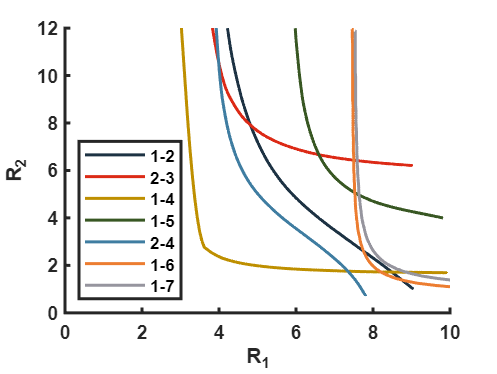


values7 = spcrv([[x7(1) x7 x7(end)];[y7(1) y7 y7(end)]],3);
plot(values7(1,:),values7(2,:),'color',[151, 150, 159]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[151, 150, 159]/256, ...
    'DisplayName','1-7');



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_2','FontName','arial','FontWeight','bold');
legend('Location','southwest');
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end


